# **IO104 - Analog and Digital Loopback**

This example shows you how to do a loopback test with the IO104 I/O module to verify the analog and digital loopback functionality of some of the input and output channels.

The IO104 is a fast, simultaneous sampling I/O module with 16-bit analog inputs and outputs, and 16 digital TTL I/O lines configurable as inputs or outputs in two groups of 8 channels.

The Simulink model features the [IO104 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io104_setup), [Analog input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io104_analog_input), [Analog output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io104_analog_output), [Digital input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io104_digital_input), and [Digital output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io104_digital_output) blocks.

## Test Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO104 I/O module installed

- Connector cable from the I/O module to the terminal board

- 80-pin terminal board with jumper wires

### Loopback Wiring

This example outputs a sine wave signal on the analog outputs. The outputs are wired back to the analog input channels, where the voltage is measured and displayed in Simulink.

A pulse generator is connected to the digital outputs. The pulse is sampled with the digital inputs.

The following wiring is required:

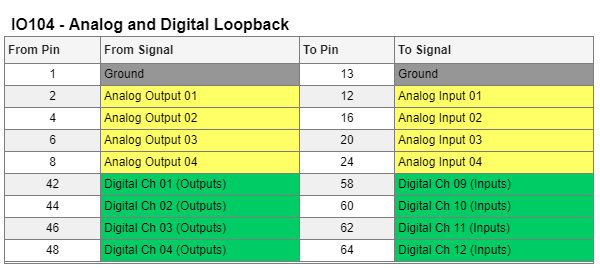

## Open Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO104_AnalogDigitalLoopback';
open_system(modelName);         

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

Open the two Simulink scopes connected to the Analog and Digital input blocks and compare the signals to check if the loopback is working as expected. On the analog scope, four sine waves with different amplitudes must be displayed, and on the Digital scope, four pulses:

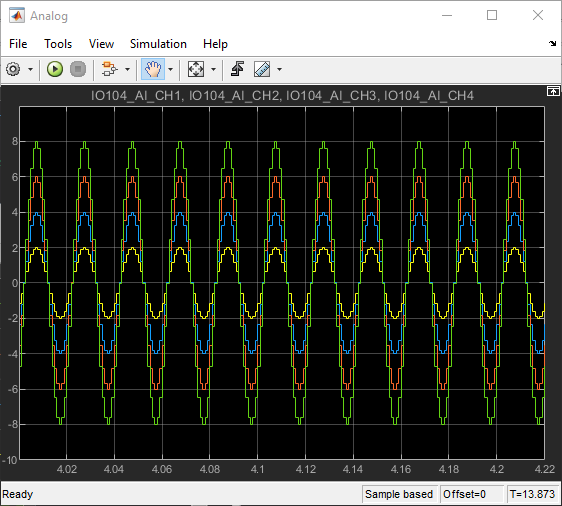 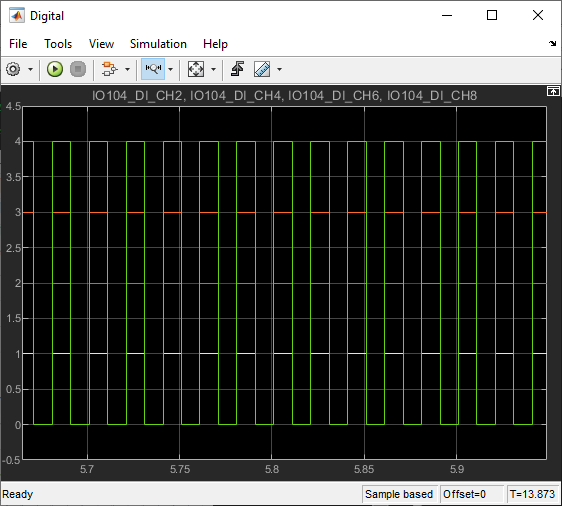

## Additional References

- [IO104 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io104)